# ME3534 Lab 4 Live Script

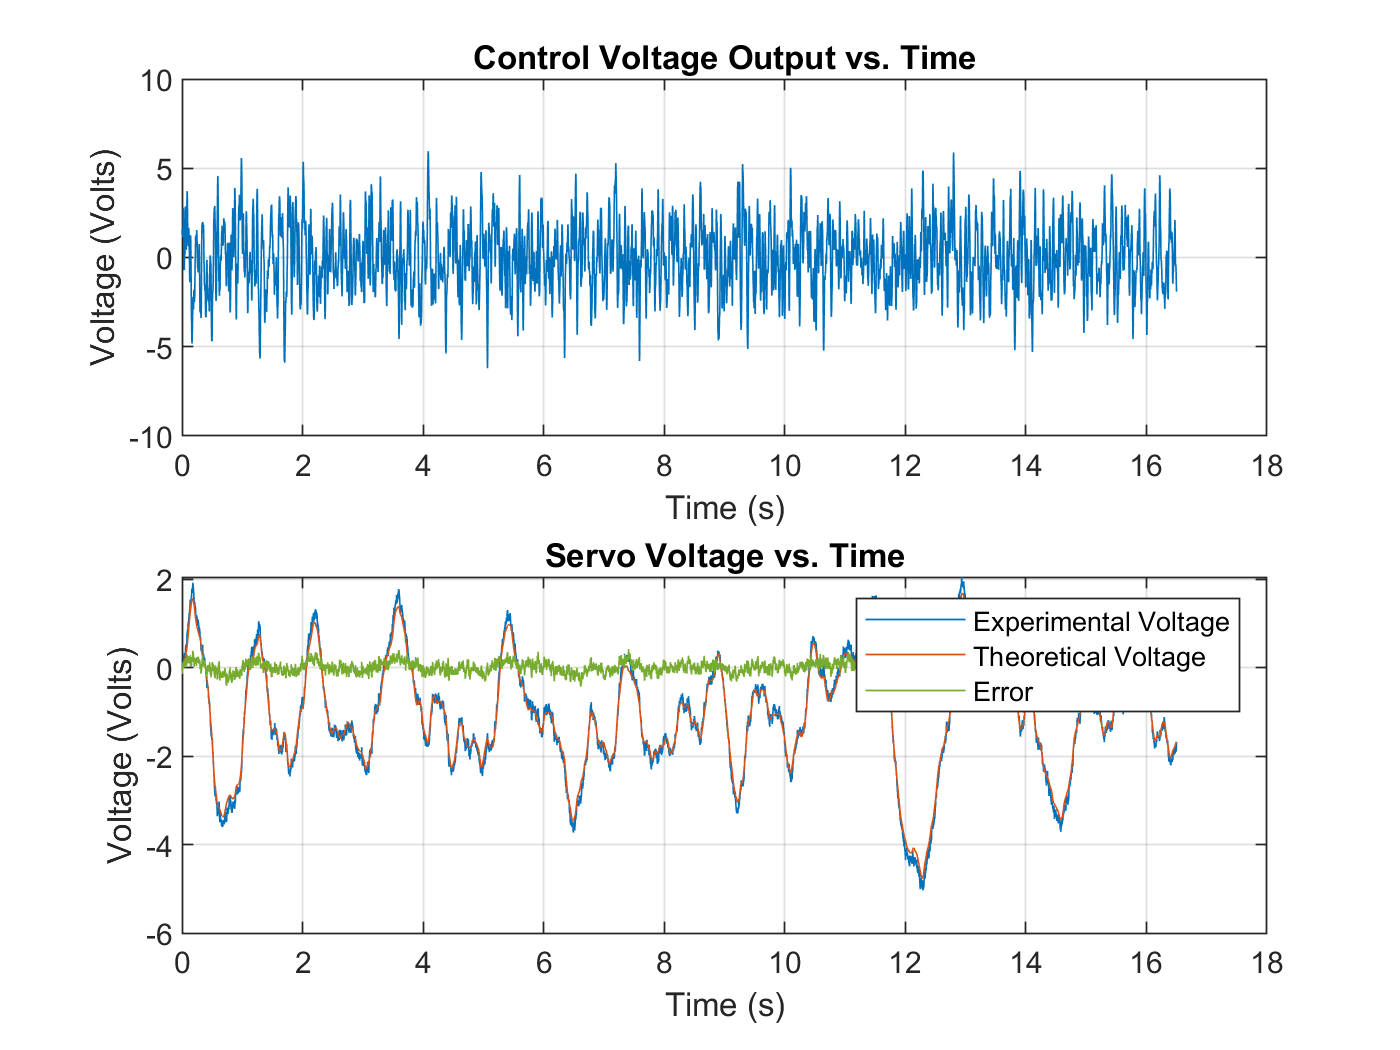

% Samuel Kramer                                                 23 MARCH 22
% 906199023                                                         ME 3534
%
% This live script is meant to analyze the data that is taken from the lab
% Will Return
%           1. Plot with 2 subplots showing control input voltage vs. time
%              and the output voltage vs. time
%              - Will also include the theoretical response to the system
%                and the error between theoretical and experimental
%           2. Plot with 3 subplots showing frequency response of the
%              system
%              - Subplots 2 and three also include the theoretical models
%                frequency response data, subplot 1 will have the coherence
%

%%%%%%%%%%%%%%%%%%%%%%%%%%% Voltage Graphs %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% -- Setup
clc; format compact; close all;

% -- Extract data from vectors
Vsens = data(:,1);
Vcontrol = data(:,2);

% -- Creating time vector
N = length(data);
ts = 1/1000;
t = ts*[0:N-1];
gain = 0.7;

% -- Define system parameters
j = 2.5*10^-5;      % Total rotational inertia 
b = 1*10^-6;        % Tota rotational damping
Kt = 0.042;         % Torque constant
Kv = 0.042;         % Velocity constant
L = 1.16*10^-3;     % Motor inductance
R = 8.4;            % Motor resistance

% -- LTI transfer function of motor
num = [0 0 0 Kt];
denom = [L*j (R*j + L*b) (R*b + Kv*Kt) 0 ];
num = num .* gain;
Hf = tf(num,denom);

% -- LSIM to simulate response data
Vsim = lsim(Hf,Vcontrol,t);

% -- Compute error and offset to to Y0
Vsens = Vsens - Vsens(1);
error = Vsens - Vsim;

% -- Plot equations 
    % Plot of Control Voltage 
subplot(2,1,1)  % Plot 1
plot(t,Vcontrol)
    grid on
    hold on
    ylim([-10 10])
    ylabel('Voltage (Volts)')
    xlabel('Time (s)')
    title('Control Voltage Input vs. Time')

    % Plot of Output data and error
subplot(2,1,2)
plot(t,Vsens)       % Plotting experimental data
    grid on
    hold on
plot(t,Vsim)        % Plotting theoretical data
    grid on
    hold on
plot(t,error,'Color',[0.4660 0.6740 0.1880])       % Plotting the error
    grid on
    hold on
    ylabel('Voltage (Volts)')
    xlabel('Time (s)')
    legend('Experimental Voltage','Theoretical Voltage','Error')
    title('Servo Voltage vs. Time')

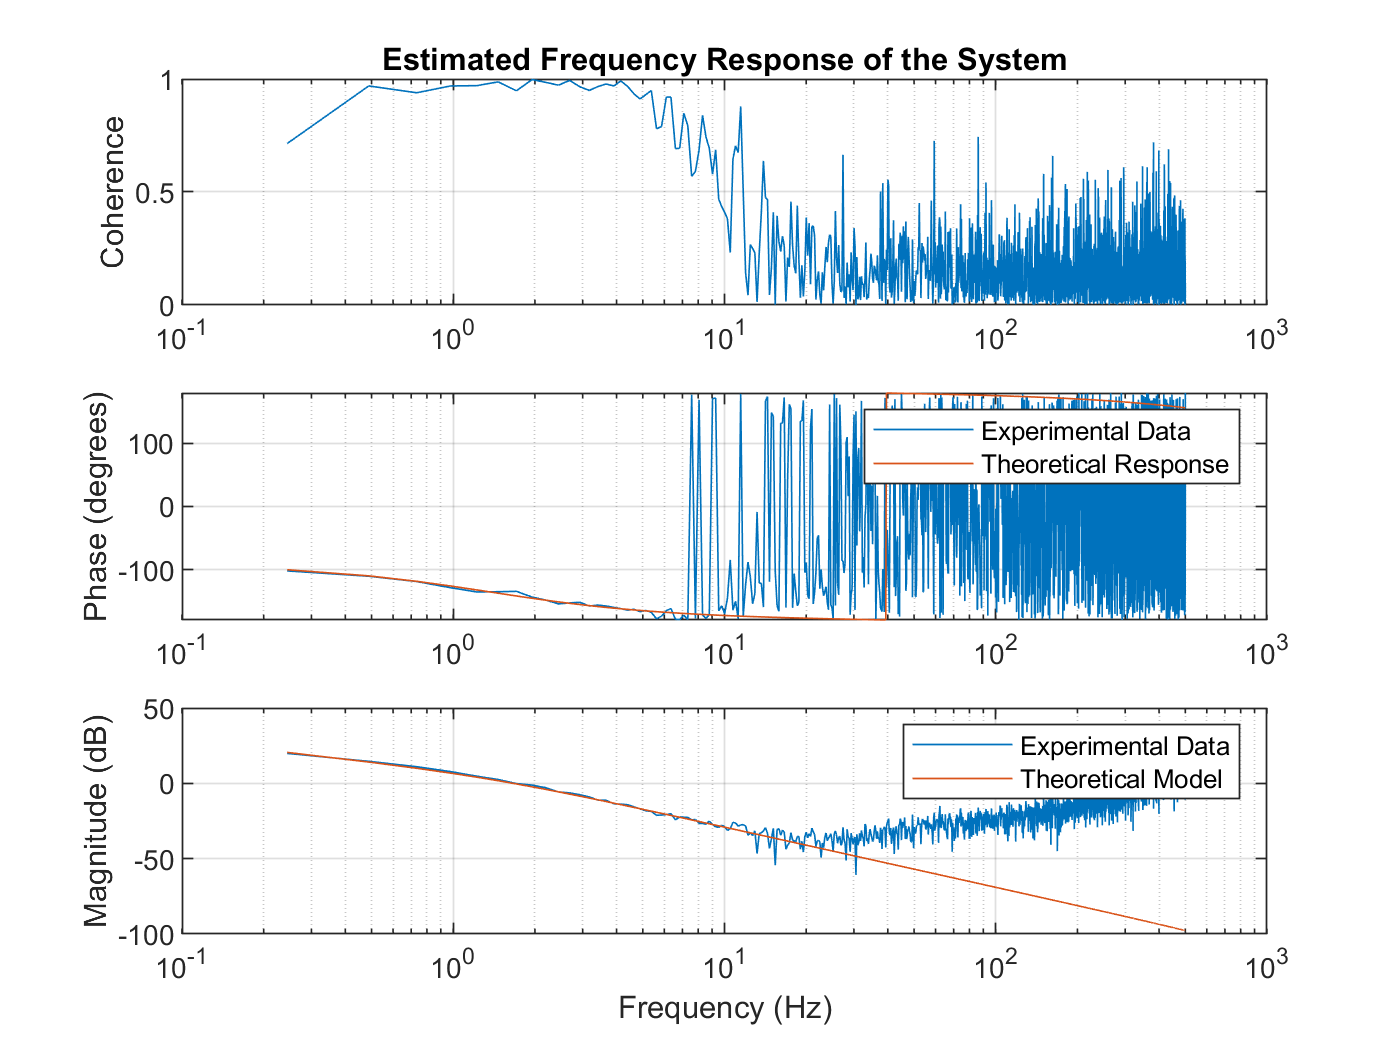


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Frequency Responses %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% -- Using tfestimate() and mscohere()

    % NFFT Definitions
        % Frequency resolution is determined by fs/NFFT 
    NFFT = 2^12;                    % Makes resolution be less that 0.25 Hz
    window = NFFT;                  % Declares window of 4096 frequency values
    overlap = NFFT/2;               % 50% overlap

    % Calculation of experimental frequency response and coherence
    [FRD,fr] = tfestimate(Vcontrol,Vsens,window,overlap,NFFT,1000);
    [COH,fr] = mscohere(Vcontrol,Vsens,window,overlap,NFFT,1000);

% -- Plot the Frequency responses

    % Subplot of Coherence
    figure                          
    subplot(3,1,1)
    semilogx(fr,COH)
        grid on
        hold on
        ylim([0 1])
        title('Estimated Frequency Response of the System')
        ylabel('Coherence')

    % Subplot of Phase
    subplot(3,1,2)                  
    semilogx(fr,(180/pi)*angle(FRD))
        grid on
        hold on
        ylim([-180 180])
        ylabel('Phase (degrees)')
    
   % Subplot of Magnitude 
    subplot(3,1,3)                   
    semilogx(fr,20*log10(abs(FRD)))     % Turns data into dB using 20*log(x)
        grid on
        hold on
        ylabel('Magnitude (dB)')
        xlabel('Frequency (Hz)')
    
% -- Using freqresp command to calculate theoretical frequency responses
    % Will use the freqresp() and the sqeeze() --> use 'help' to get more
    % info on how to use these commands

    % Frequency response
    Freq = squeeze(freqresp(Hf,2*pi*fr));
    subplot(3,1,2)
    semilogx(fr,(180/pi)*angle(Freq))
        hold on
        legend('Experimental Data','Theoretical Response')
    
    % Decibel response of system
    subplot(3,1,3)
    semilogx(fr,20*log10(abs(Freq)))
        hold on
        legend('Experimental Data','Theoretical Model')


% End of code  
